# anti-Winner-take-all (anti-WTA) in L2/3, buit L5 in ordered pattern

clear;
clc;
addpath('../funcs');
% load ../../data/allpsd_0_0.5_0_0.05_Iattn_0.02.mat;
load ../../data/all5000_levelMethod2_0_0.5_0_0.05_Iattn_0.02.mat;
levelSheet = levelSheet*1000;

pops = ["1L2/3E","1L2/3I","1L4E","1L4I","1L5E","1L5I","1L6E","1L6I"];
conds = ["original", "S1", "S2", "S1S2", "S1S2+A1", "S1S2+A2"];

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 10;
steps = size(levelSheet,1);
pop = 5;


## rule out by PSD peaks

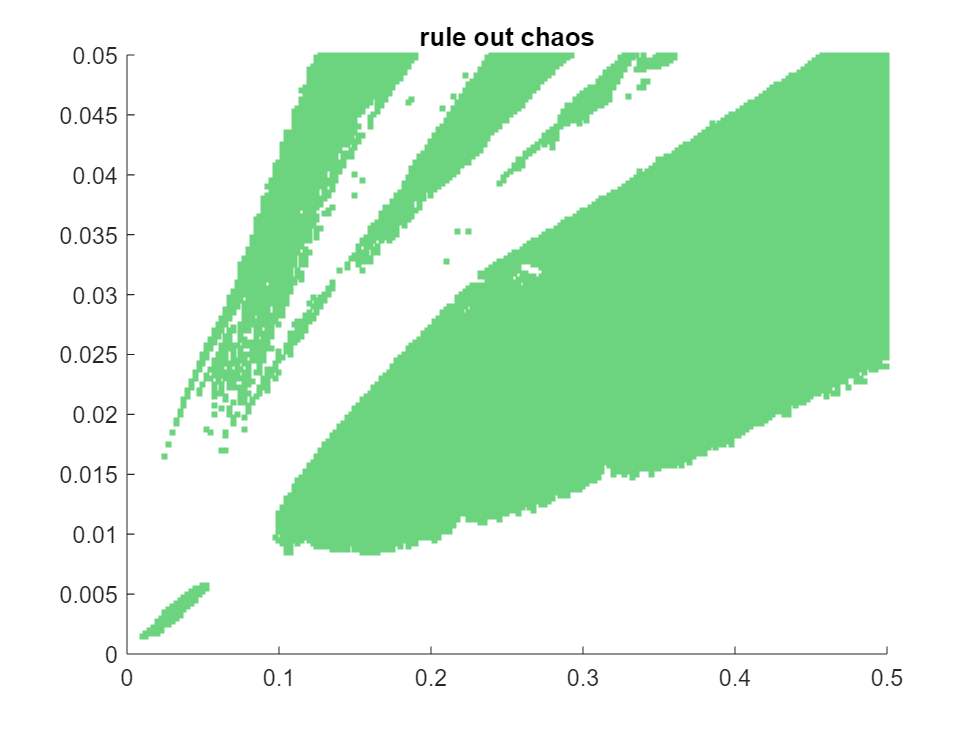

ruleOut = zeros(steps,steps);
maxPks = 4;

for i = 1:steps
    for j = 1:steps
        cond0 = psdPeaksSheet(i,j,pop,1); cond1 = psdPeaksSheet(i,j,pop,2); cond2 = psdPeaksSheet(i,j,pop,3);
        cond3 = psdPeaksSheet(i,j,pop,3); cond4 = psdPeaksSheet(i,j,pop,5); cond5 = psdPeaksSheet(i,j,pop,6);
        tmp = max([cond0 cond1 cond2 cond3 cond4 cond5]);
        if tmp<=maxPks && tmp>=1 
            ruleOut(i,j) = 1;
        end
    end
end

ruleOut = ruleOut == 1;

figure();
for i = 1:steps
    x = Delta_e(ruleOut(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("rule out chaos");

## L5 in order: by mean of firing rate

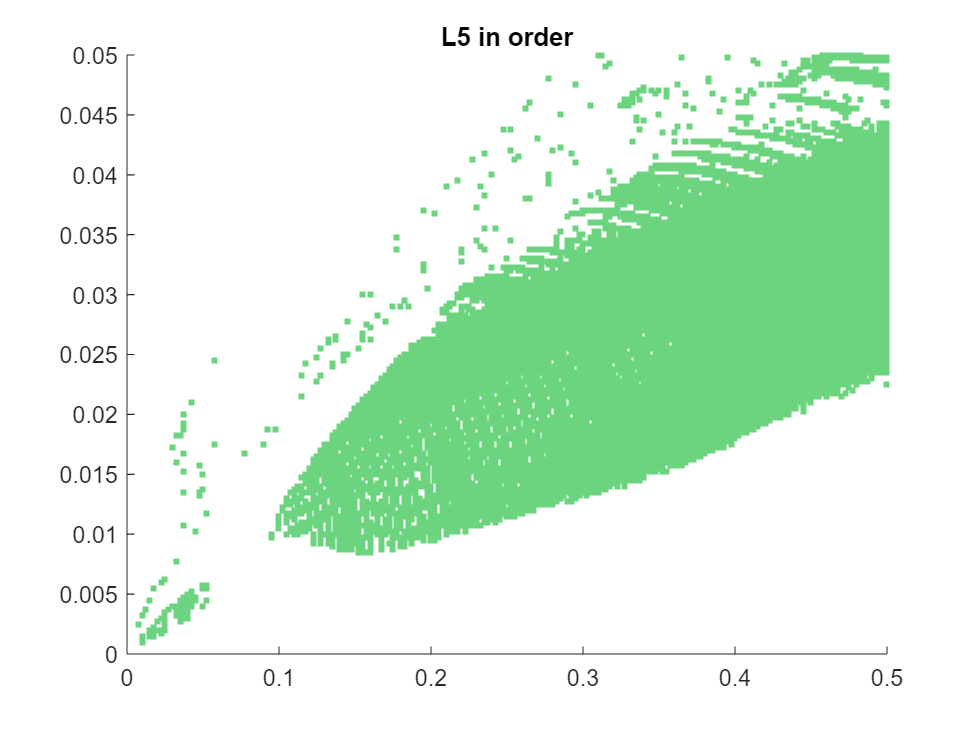

order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

order = order == 1;

figure();
for i = 1:steps
    x = Delta_e(order(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L5 in order");

## L5 in order: by mean of envelop of firing rate

% load ../../data/allpsd_0_0.5_0_0.05_Iattn_0.02.mat;
% order = zeros(steps,steps);
% 
% for i = 1:steps
%     for j = 1:steps
%         cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
%         cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
%         if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
%             order(i,j) = 1;
%         end
%     end
% end
% 
% order = order == 1;
% 
% figure();
% for i = 1:steps
%     x = Delta_e(order(steps+1-i,:));
%     y = Delta_i(i)*ones(length(x),1);
%     s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
%     hold on;
% end
% hold off;
% axis([0 0.5 0 0.05]);
% title("L5 in order (envelop)");

## L2/3 WTA

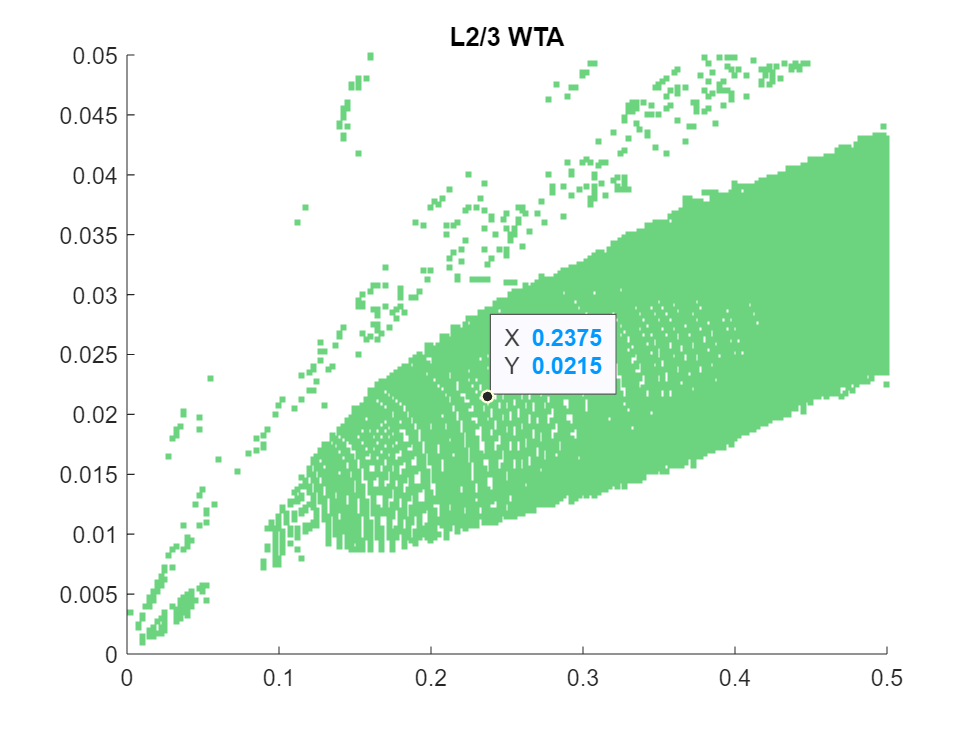

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L2/3 WTA");

## L2/3 anti-WTA: sensory

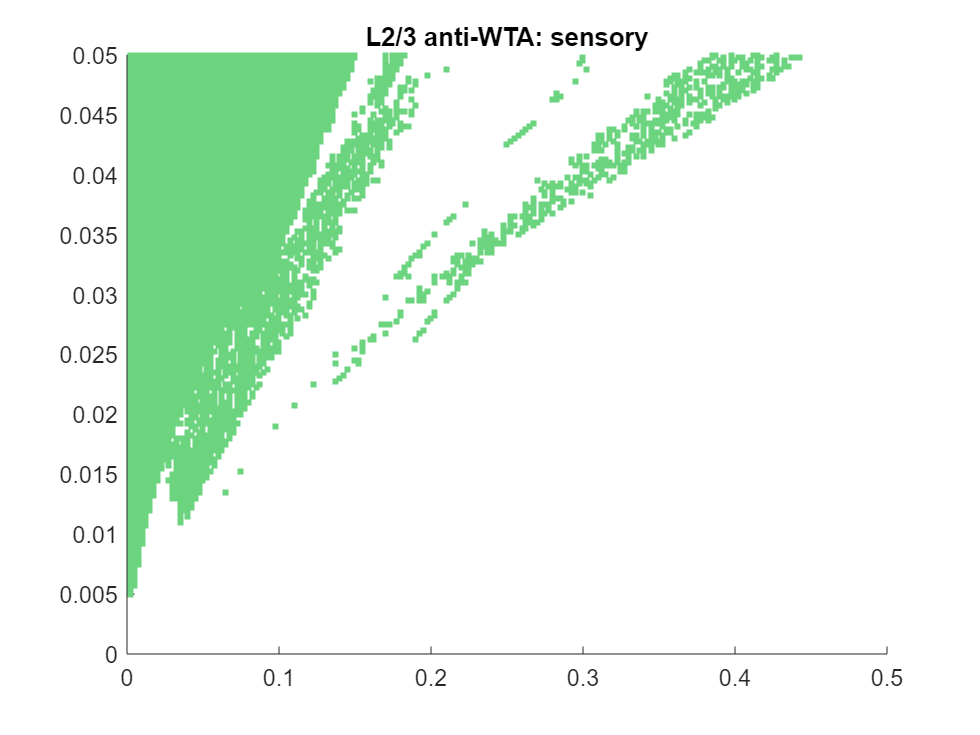

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1<cond2
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L2/3 anti-WTA: sensory");

## L2/3 anti-WTA: attention

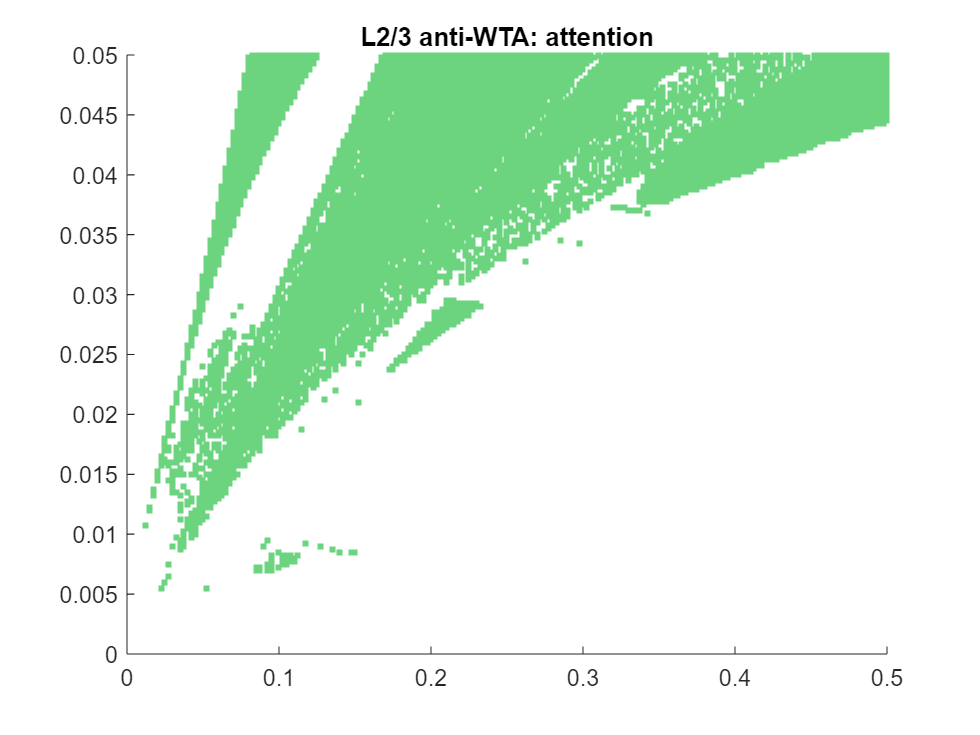

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        % if cond4<cond3 && cond3<cond5
        if cond4<cond5
            antiWTA(i,j) = 1;
        end
    end
end

antiWTA = antiWTA == 1;

figure();
for i = 1:steps
    x = Delta_e(antiWTA(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("L2/3 anti-WTA: attention");

## combine L5 in order and L2/3 anti-WTA attention

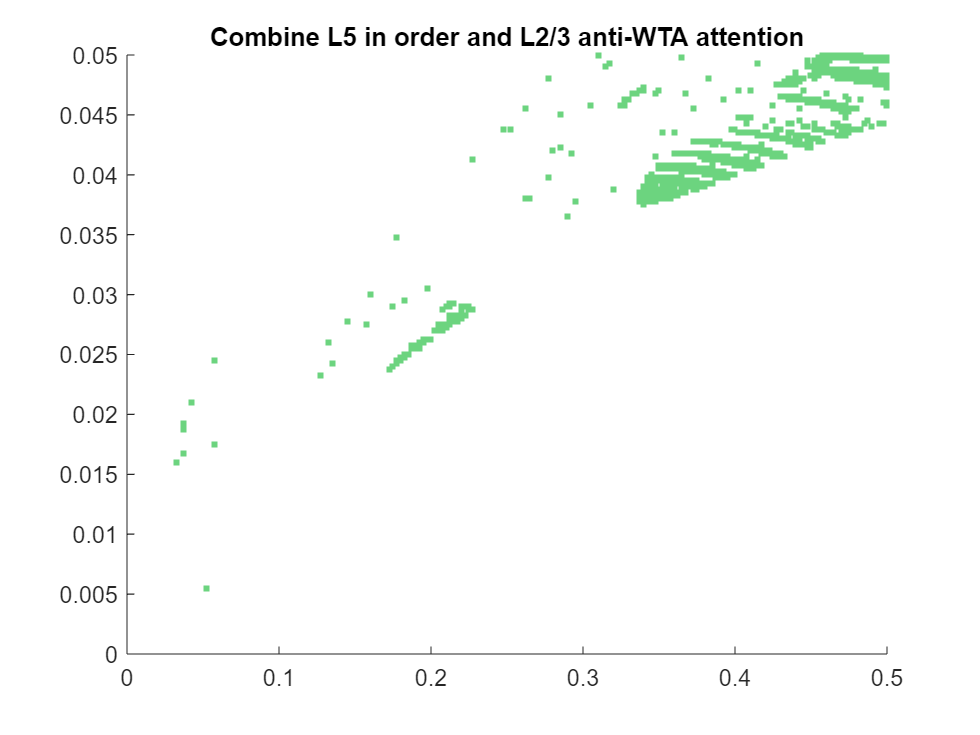

pop = 5;

order = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        if cond1>cond3 && cond4>cond3 && cond3>cond2 && cond3>cond5
            order(i,j) = 1;
        end
    end
end

pop = 1;
antiWTA = zeros(steps,steps);

for i = 1:steps
    for j = 1:steps
        cond0 = levelSheet(i,j,pop,1); cond1 = levelSheet(i,j,pop,2); cond2 = levelSheet(i,j,pop,3);
        cond3 = levelSheet(i,j,pop,4); cond4 = levelSheet(i,j,pop,5); cond5 = levelSheet(i,j,pop,6);
        % if cond4<cond3 && cond3<cond5
        if cond4<cond5
            antiWTA(i,j) = 1;
        end
    end
end

combine = order.*antiWTA;
combine = combine == 1;

figure();
for i = 1:steps
    x = Delta_e(combine(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % green
    hold on;
end
hold off;
axis([0 0.5 0 0.05]);
title("Combine L5 in order and L2/3 anti-WTA attention");

## try some dots: 2 yellow

pop = 5;
dt = 0.01;
time = 5000;
timeax = 0:dt:time;
timeax = timeax';
DeltaE = 0.48;
DeltaI = 0.048;
filename = append('DeltaE ', num2str(DeltaE), ' DeltaI ', num2str(DeltaI));

[r, v, g] = once(DeltaE, DeltaI, 0.02, time);
r = r*1000;

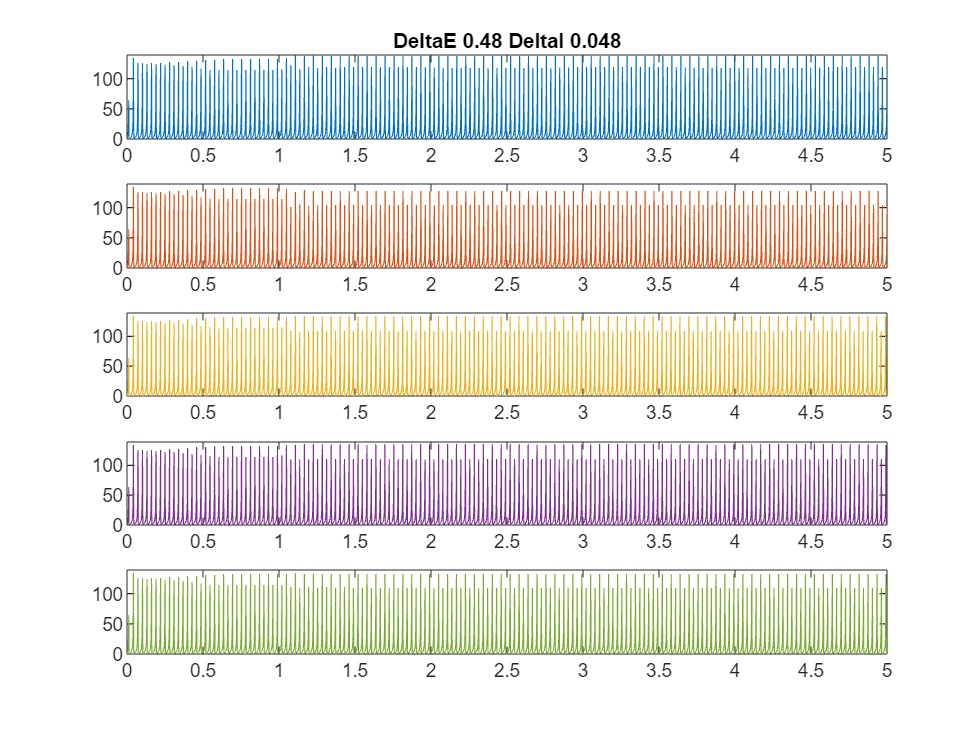

figure();
tiledlayout(5,1)
ax1 = nexttile;
plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD');
title(filename);
hold on

ax2 = nexttile;
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319');
hold on

ax3 = nexttile;
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120');
hold on

ax4 = nexttile;
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E');
hold on
    
ax5 = nexttile;
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30');
hold on

linkaxes([ax1 ax2 ax3 ax4 ax5],'xy');
% ax1.YLim = [low maxDurStim*1.1];

hold off;

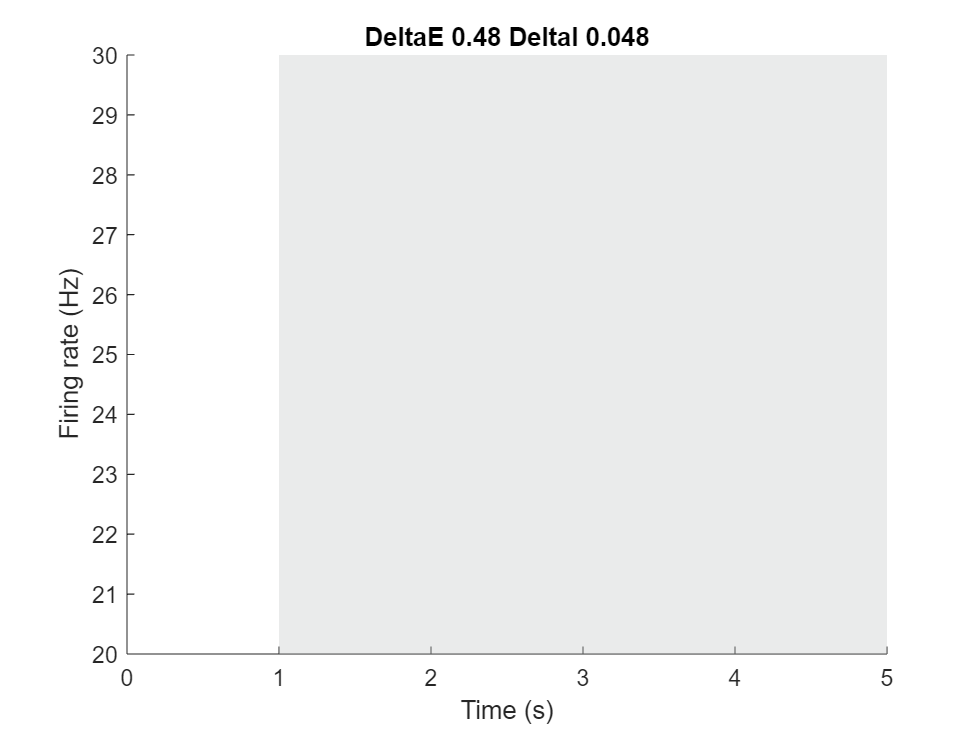


figure();
hold on;
recX = [1 time/1000 time/1000 1];
recY = [0 0 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.3);

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;
stimIn = 1000;
stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

r_cond1 = r(5,:,1);
r_cond1 = r_cond1';

r_cond2 = r(5,:,2);
r_cond2 = r_cond2';

r_cond3 = r(5,:,3);
r_cond3 = r_cond3';

r_cond4 = r(5,:,4);
r_cond4 = r_cond4';

r_cond5 = r(5,:,5);
r_cond5 = r_cond5';

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(r_cond1(1:step_stimIn),envWdo,envMthd);
[cond2BF, ] = envelope(r_cond2(1:step_stimIn),envWdo,envMthd);
[cond3BF, ] = envelope(r_cond3(1:step_stimIn),envWdo,envMthd);
[cond4BF, ] = envelope(r_cond4(1:step_stimIn),envWdo,envMthd);
[cond5BF, ] = envelope(r_cond5(1:step_stimIn),envWdo,envMthd);

[cond1AF, ] = envelope(r_cond1(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond2AF, ] = envelope(r_cond2(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond3AF, ] = envelope(r_cond3(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond4AF, ] = envelope(r_cond4(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);
[cond5AF, ] = envelope(r_cond5(step_stimIn+1:step_stimIn+step_stim+1),envWdo,envMthd);

cond1Up = cat(1, cond1BF, cond1AF);
cond2Up = cat(1, cond2BF, cond2AF);
cond3Up = cat(1, cond3BF, cond3AF);
cond4Up = cat(1, cond4BF, cond4AF);
cond5Up = cat(1, cond5BF, cond5AF);

plot(timeax,cond1Up,'Color','#0072BD','LineWidth',2);
plot(timeax,cond3Up,'Color','#EDB120','LineWidth',2);
plot(timeax,cond4Up,'Color','#7E2F8E','LineWidth',2);
plot(timeax,cond5Up,'Color','#77AC30','LineWidth',2);
plot(timeax,cond2Up,'Color','#D95319','LineWidth',2);


title(filename);

axis([0 time/1000 20 30]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;

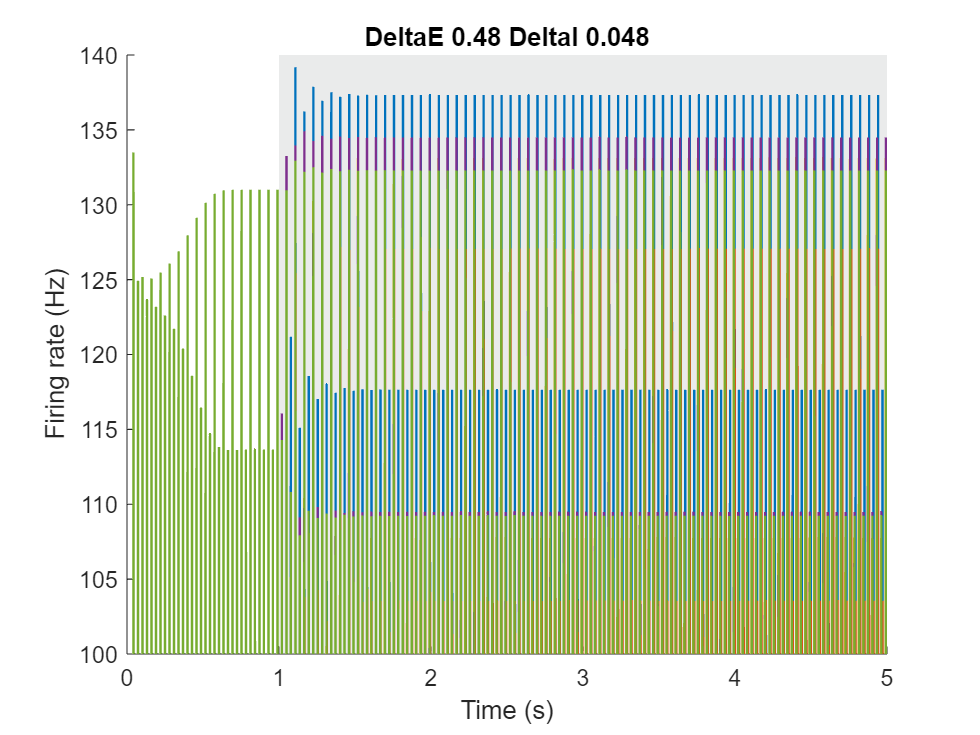



figure();
hold on;

recX = [1 time/1000 time/1000 1];
recY = [0 0 190 190];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.3);

plot(timeax,r_cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,r_cond2,'Color','#D95319','LineWidth',1);
plot(timeax,r_cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,r_cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,r_cond5,'Color','#77AC30','LineWidth',1);

title(filename);

axis([0 time/1000 100 140]);
xlabel("Time (s)");
ylabel("Firing rate (Hz)");
hold off;